% trying to integrate the imporved solver with the varying geometry
clear; close all;

% Permissivity
eps0 = 8.854187817e-12;

% Grid & domain
Nx = 20; Ny = 20; % number of grid points in each dir
Lx = 100.0; Ly = 100.0; Lz = 1; % grid dimensions (meters) - currently cube
dx = Lx/Nx; dy = Ly/Ny;
xl = linspace(0, Lx, Nx);
yl = linspace(0, Ly, Ny);
zlb = zeros(Nx, Ny);
zlt = zeros(Nx, Ny);

z_bot = @(x, y) 0; % function that describes z of top and bottom plates
z_top = @(x, y) Lz; 
top_valid_num = 150; % xy_top and xy_bottom should both evaluate to be less than or equal to C
xy_top = @(x, y) x+y;
bot_valid_num = 10000;
xy_bot= @(x, y) (x-Lx/2)^2 + (y-Ly/2)^2;
delt_V = 10; % Voltage across the plates
A_patch = dx*dy; % area of one patch


V = transpose(zeros(1, Nx*2*Ny));
V(Nx*Ny+1:Nx*Ny*2) = delt_V; % top plate voltage is voltage difference, bottom plate stays 0

% solving for voltage
% initalizing a matrix contianing all of the position vectors
r = zeros(Nx*Ny*2, 3); % r is list/vector of all the position vectors
for i = 1:Nx
    for j = 1:Ny
        x_coord = (i-0.5)*dx;
        y_coord = (j-0.5)*dy;
        valid_top_coord = xy_top(x_coord, y_coord); % plug xy coordinate into the equation for the top and bottom surfaces to check if this point is allowed
        valid_bot_coord = xy_bot(x_coord, y_coord);
        if (valid_top_coord <= top_valid_num) % for a circle, x^2 + y^2 <= r^2 -- this is what this checks
            zlt(i, j) = z_top(x_coord, y_coord); 
            r((i-1)*Nx + j + Nx*Ny, :) = [x_coord, y_coord, z_top(i, j)];
        else  % if the mesh point falls outside of the allowed xy region
            zlt(i, j) = NaN;
            r((i-1)*Nx + j + Nx*Ny, :) = [NaN, NaN, NaN];
        end
        if (valid_bot_coord <= bot_valid_num) % for a circle, x^2 + y^2 <= r^2 -- this is what this checks
            zlb(i, j) = z_bot(x_coord, y_coord); 
            r((i-1)*Ny + j, :) = [x_coord, y_coord, z_bot(i, j)];
        else  % if the mesh point falls outside of the allowed xy region
            zlb(i, j) = NaN;
            r((i-1)*Ny + j, :) = [NaN, NaN, NaN];
        end
    end
end

% G is matrix used to relate V at each point to rho, charge density
% Gij = Aj/(4 pi epsilon |ri - rj|), ri is vector to center of patch on 0
% plate, rj is vector to center of patch on V = 1 plate
% there are Nx*Ny patches on each plate

G = zeros(Nx*Ny*2, Nx*Ny*2); 

for i = 1:(Nx*Ny*2)
    for j = 1:(Nx*Ny*2)
        if ~anynan(r(i, :)) && ~anynan(r(j, :))
            deltR = r(i, :) - r(j, :); % ri - rj
            if (i ~= j) % if the distance between points is not zero
                G(i, j) = A_patch/norm(deltR)/ (4 * pi * eps0); % regular Gij formula
            else
                G(i, j) = dy/(pi * eps0) * log(1+ 2^0.5); % self term approximation if i = j
            end
        end
    end
end

% Know that G * rho = V, so can calc rho as the inverse of G times V
rho = V \ G

rho = 1.0e+08 *

    4.4871    4.8411    5.0870    5.2736    5.4183    5.5298    5.6133    5.6720    5.7078    5.7221    5.7156    5.6884    5.6400    5.5695    5.4749    5.3533    5.1997    5.0055    4.7535    4.3948    4.8411    5.2654    5.5528    5.7660    5.9289    6.0530    6.1450    6.2093    6.2482    6.2634    6.2558    6.2255    6.1719    6.0938    5.9888    5.8531    5.6802    5.4584    5.1643    4.7349    5.0870    5.5528    5.8710    6.1063    6.2849    6.4201    6.5199    6.5891    6.6306    6.6464


rho_top = rho(Ny*Nx+1:2*Ny*Nx)

rho_top = 1.0e+08 *

    4.3289    4.6862    4.9328    5.1196    5.2645    5.3761    5.4597    5.5184    5.5542    5.5686    5.5620    5.5348    5.4864    5.4158    5.3212    5.1995    5.0458    4.8513    4.5986    4.2366    4.6862    5.1146    5.4029    5.6165    5.7795    5.9037    5.9958    6.0601    6.0990    6.1143    6.1067    6.0763    6.0227    5.9446    5.8395    5.7037    5.5306    5.3085    5.0134    4.5800    4.9328    5.4029    5.7221    5.9578    6.1366    6.2719    6.3718    6.4410    6.4825    6.4983


rho_bot = rho(1:Ny*Nx)

rho_bot = 1.0e+08 *

    4.4871    4.8411    5.0870    5.2736    5.4183    5.5298    5.6133    5.6720    5.7078    5.7221    5.7156    5.6884    5.6400    5.5695    5.4749    5.3533    5.1997    5.0055    4.7535    4.3948    4.8411    5.2654    5.5528    5.7660    5.9289    6.0530    6.1450    6.2093    6.2482    6.2634    6.2558    6.2255    6.1719    6.0938    5.9888    5.8531    5.6802    5.4584    5.1643    4.7349    5.0870    5.5528    5.8710    6.1063    6.2849    6.4201    6.5199    6.5891    6.6306    6.6464



% charge on plate is then sum of charge density on each patch times area of
% patch
Q_tot_top = abs(sum(rho_top))*A_patch % equal patch sizes

Q_tot_top = 5.5522e+12

C_top = Q_tot_top/delt_V % capacitance

C_top = 5.5522e+11

Q_tot_bot = abs(sum(rho_bot)) * A_patch

Q_tot_bot = 6.1153e+12

C_bot = Q_tot_bot/delt_V

C_bot = 6.1153e+11


C = (C_bot + C_top)/2 % averaging capacitance calculated from top and bottom

C = 5.8338e+11

Error_Estimate = abs(Q_tot_top-Q_tot_bot)/Q_tot_top

Error_Estimate = 0.1014

C_ana = Lx*Ly/Lz*eps0

C_ana = 8.8542e-08

C_ratio = C/C_ana

C_ratio = 6.5887e+18

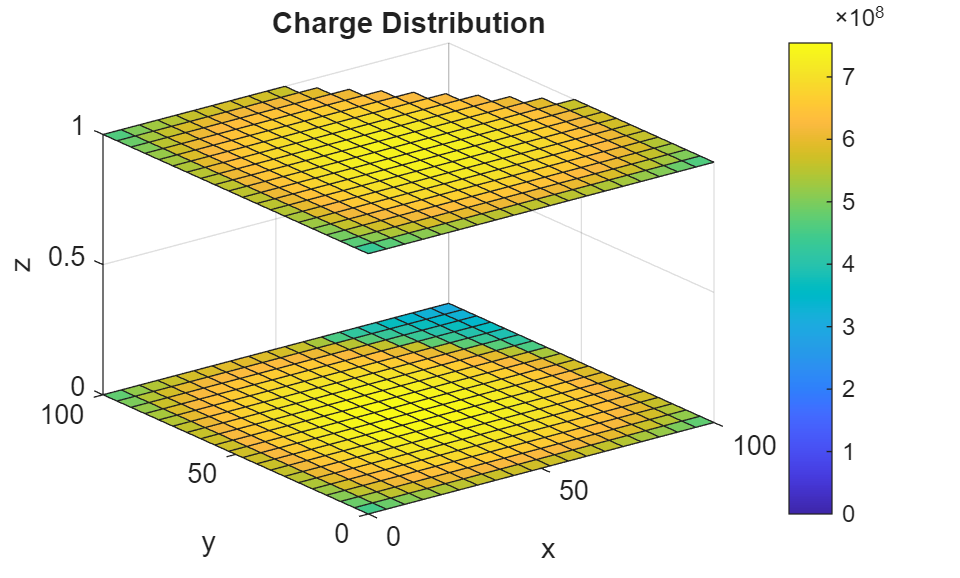


Colour_top = zeros(Nx, Ny);
Colour_bot = zeros(Nx, Ny);

% Initalize the charge density colormap
for i = 1:(Nx)
    for j = 1:(Nx)
        % colour at point i, j will correspond to the charge density at the
        % same point
        Colour_top(i, j) = abs(rho_top((i-1)*Nx + j)); % making a color matrix using the charge density
        Colour_bot(i, j) = abs(rho_bot((i-1)*Nx + j)); 
    end
end

figure;
surf(xl, yl, zlb, Colour_bot);
hold on;
surf(xl, yl, zlt, Colour_top);
colorbar;
xlabel('x');
ylabel('y');
zlabel('z');
title('Charge Distribution');
hold off;

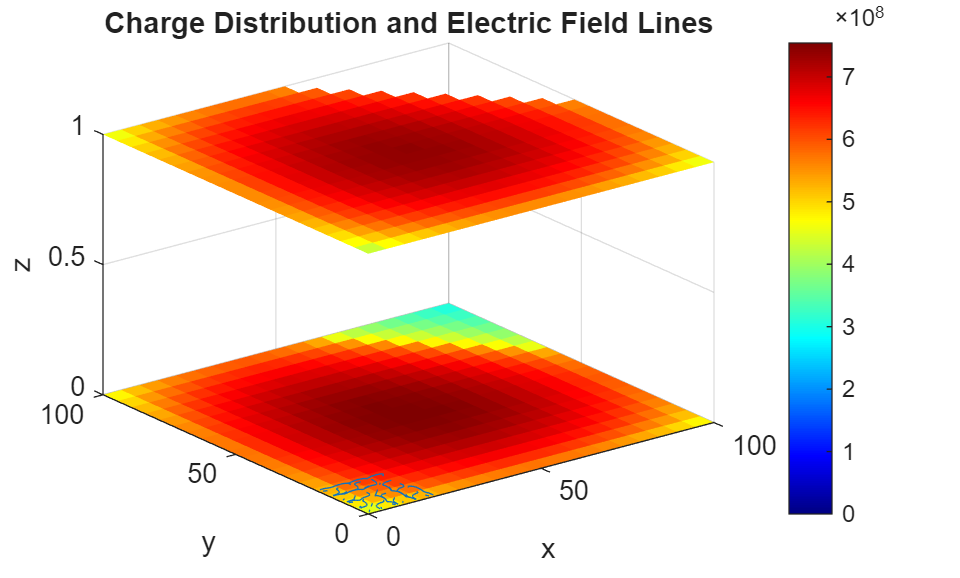


% Calculate the electric field
z_mid = mean([nanmean(zlb(:)), nanmean(zlt(:))]); % mid-plane between plates

NxE = 100; NyE = 100;
[xE, yE] = meshgrid(linspace(1, Nx, NxE), linspace(1, Ny, NyE));

Ex = zeros(size(xE)); % Electric field components
Ey = zeros(size(yE));
Ez = zeros(size(xE));

for ix = 1:numel(xE)
    r_field = [xE(ix), yE(ix), z_mid];
    E = [0, 0, 0];

    for j = 1:(2*Nx*Ny)
        if ~anynan(r(j,:))
            R = r_field - r(j,:);
            Rmag = norm(R);
            if Rmag > 0
                E = E + rho(j) * A_patch * R / Rmag^3; % Electric field at that point based off of charge density
            end
        end
    end

    E = E / (4*pi*eps0);
    Ex(ix) = E(1);
    Ey(ix) = E(2);
    Ez(ix) = E(3);
end

% Normalizing the electric field
Emag = sqrt(Ex.^2 + Ey.^2);
Exn = Ex ./ Emag;
Eyn = Ey ./ Emag;

% Starting points for field lines
[startX, startY] = meshgrid(linspace(2, Nx-2, 6), linspace(2, Ny-2, 6));

figure;
surf(xl, yl, zlb, Colour_bot, 'EdgeColor','none');
hold on;
surf(xl, yl, zlt, Colour_top, 'EdgeColor','none');

% Plot field lines in mid-plane
streamline(xE, yE, Exn, Eyn, startX, startY);

colormap jet;
colorbar;
xlabel('x');
ylabel('y');
zlabel('z');
title('Charge Distribution and Electric Field Lines');
view(3);
axis tight;